Uppgift a)

Blir en kvdrat p.g.a. två värden multiplicerat med varandra

N = 100000

N = 100000

F = [];
dim = 2

dim = 2

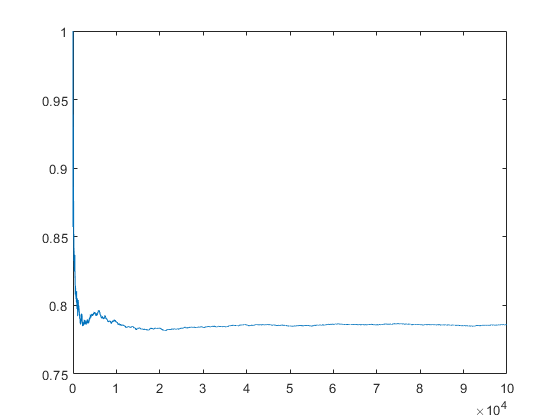

A = 2*rand(N, dim)-1;


for i = 1:N
    if(norm(A(i,:)) <= 1)
        F(i,1) = 1;
    else
        F(i,1) = 0;
    end
    F(i,2) =sum(F(:,1))/i;
end
figure
title('Förhållande mellan cirkel och kvadrat (radie=1)')
ylabel('Förhållande')
xlabel('Antal genererade punkter')
plot(1:N,F(:, 2));

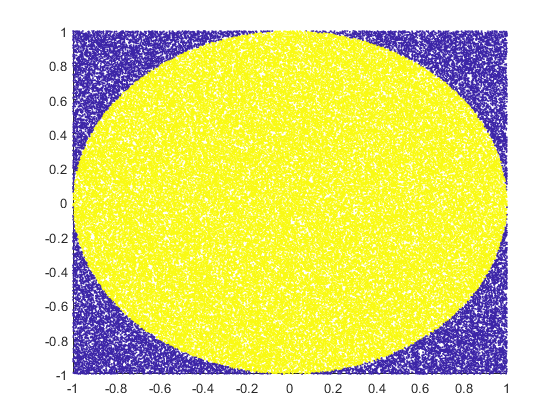

figure
scatter(A(:,1),A(:,2),1,F(:,1))

Uppgift 2

dim = 30

dim = 30

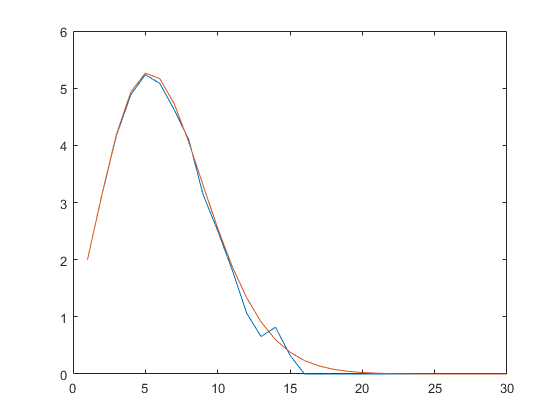

F = zeros(N, 2);
dimVector= zeros(dim, 2);
A = 2*rand(N, dim)-1;


for j = 1:dim
    
    for i = 1:N
        if(norm(A(i,1:j)) <= 1)
            F(i,1) = 1;
        else
            F(i,1) = 0;
        end
    end
    dimVector(j, 1) = (sum(F(:, 1))/N)*2^j;
    dimVector(j, 2) = ((pi^(j/2))/gamma((j/2 + 1)));
end
figure
title('Volymen av en hypersfär med punkter genererade i en hyperkub')
xlabel('Dimensioner')
ylabel('Volym på hypersfär')
plot(1:dim,dimVector(:,1),1:dim, dimVector(:,2));